% (x+sin(y))*dx+(x*cos(y)+sin(y))*dy=0

% y'=-(x+sin(y))/(x*cos(y)+sin(y))
syms x y(x)
% 1)
eqn=diff(y(x))+(x+sin(y))/(x*cos(y)+sin(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)+\frac{x+\sin\left(y\left(x\right)\right)}{\sin\left(y\left(x\right)\right)+x\,\cos\left(y\left(x\right)\right)}$$

% ySol=dsolve(eqn)
% don't work((

% 2)
syms x y
P(x,y)=x+sin(y)

$$P(x, y) = x+\sin\left(y\right)$$

Q(x,y)=x*cos(y)+sin(y)

$$Q(x, y) = \sin\left(y\right)+x\,\cos\left(y\right)$$

chk1=diff(P,y)-diff(Q,x)

$$chk1(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = C\left(y\right)+\frac{x\,\left(x+2\,\sin\left(y\right)\right)}{2}$$

% C(y) + (x*(x + 2*sin(y)))/2
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+x\,\cos\left(y\right)$$

% diff(C(y), y) + x*cos(y) == Q(x,y) == x*cos(y)+sin(y)
% diff(C(y), y) == sin(y)
C1(y)=int(sin(y),y)

$$C1(y) = -\cos\left(y\right)$$

% -cos(y)
U=subs(U,C(y),C1(y))

$$U = \frac{x\,\left(x+2\,\sin\left(y\right)\right)}{2}-\cos\left(y\right)$$

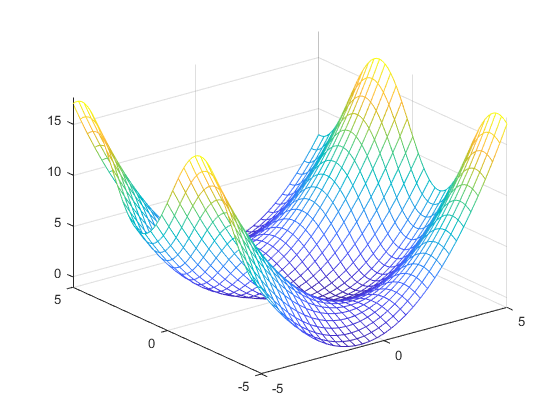

% (x*(x + 2*sin(y)))/2 - cos(y) = C
% x^2/2 + x*sin(y) - cos(y) = C
fmesh(U)


% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = \frac{x\,\left(x+2\,\sin\left(y\right)\right)}{2}-\cos\left(y\right)+1$$

syms C
eq2=U-1==C

$$eq2 = \frac{x\,\left(x+2\,\sin\left(y\right)\right)}{2}-\cos\left(y\right)=C$$